tsunamis

tsunamis = 162×20 table
    Latitude    Longitude    Year    Month    Day    Hour    Minute    Second    ValidityCode            Validity             CauseCode             Cause              EarthquakeMagnitude          Country                         Location                   MaxHeight    IidaMagnitude    Intensity    NumDeaths    DescDeaths
    ________    _________    ____    _____    ___    ____    ______    ______    ____________    _________________________    _________<

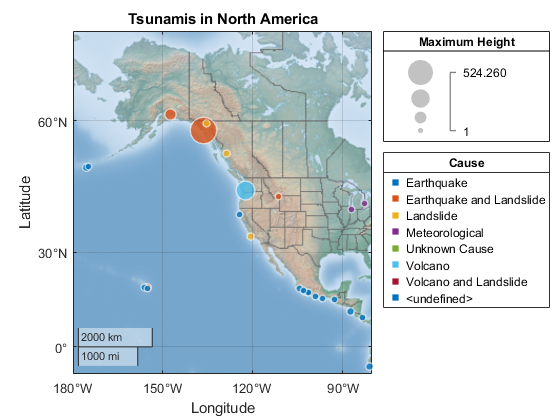

tsunamis = readtable('tsunamis.xlsx');
tsunamis.Cause = categorical(tsunamis.Cause);
figure
gb = geobubble(tsunamis,'Latitude','Longitude', ...
        'SizeVariable','MaxHeight','ColorVariable','Cause');
geolimits([10 65],[-180 -80])
title 'Tsunamis in North America';
gb.SizeLegendTitle = 'Maximum Height';
geobasemap colorterrain